%% AUTOENCODER SU VOLTI (MLX)
% Questo script addestra un semplice autoencoder (fully connected)
% sui dati dei volti e visualizza le ricostruzioni.
% Tutto fatto "a mano", senza toolbox esterni.

%% Parametri di addestramento
epochs        = 50;
learning_rate = 0.01;
bottleneck    = 40;   % dimensione del codice

%% Caricamento del dataset
disp('>>> Caricamento dataset...');

>>> Caricamento dataset...


load('dataset/volti_dataset.mat');  % A (m x n)
[m, n] = size(A);
img_h = 112; img_w = 92;
A = double(A) / 255;  % Normalizza per stabilità numerica

%% Prepara X = [n_samples x input_dim]
% Ogni riga è un'immagine
X = A';  % [n x m]

%% Training autoencoder
disp(['>>> Training autoencoder (bottleneck = ' num2str(bottleneck) ')...']);

>>> Training autoencoder (bottleneck = 40)...


tic;
[W_enc, b_enc, W_dec, b_dec, loss_history] = ...
    autoencoder_train(X, bottleneck, epochs, learning_rate);

[AE] Epoch 10/50, MSE=0.23155
[AE] Epoch 20/50, MSE=0.22831
[AE] Epoch 30/50, MSE=0.22512
[AE] Epoch 40/50, MSE=0.22197
[AE] Epoch 50/50, MSE=0.21888


fprintf('Fine training in %.2f s\n', toc);

Fine training in 96.81 s


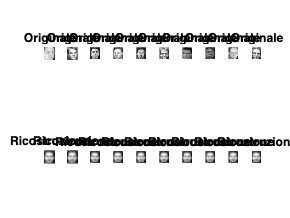


%% Visualizzazione ricostruzioni
% Scegli alcune immagini a caso dal dataset e confronta
num_show = 10;
perm = randperm(n, num_show);

figure('Name', 'Autoencoder: ricostruzioni', 'NumberTitle', 'off');
for i = 1:num_show
    x = X(perm(i), :)';  % esempio random (colonna)
    h = max(0, W_enc * x + b_enc);       % encoding + ReLU
    x_rec = W_dec * h + b_dec;           % decoding (lineare)
    subplot(2, num_show, i);
    imshow(reshape(x, img_h, img_w), []);
    title('Originale');
    subplot(2, num_show, i+num_show);
    imshow(reshape(x_rec, img_h, img_w), []);
    title('Ricostruzione');
end

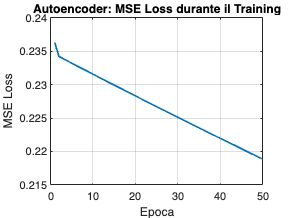


%% Andamento della loss
figure;
plot(1:epochs, loss_history, 'LineWidth',1.5);
xlabel('Epoca');
ylabel('MSE Loss');
title('Autoencoder: MSE Loss durante il Training');
grid on;